# Analog Communication Modulations

## Niusha Mirhakimi

clc; clear; close all;

## Part 1

First the sampling frequency is set to 600Hz and then the signals are generated. Below is the plot of the original signal and its fourier transform:

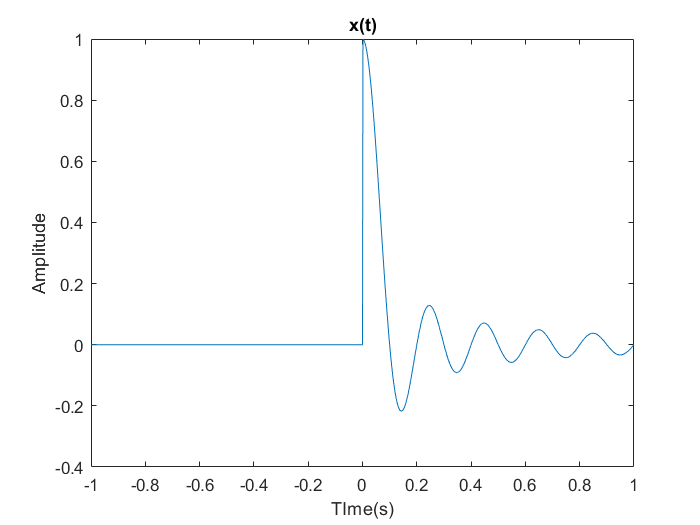

fs = 600;
t = -1 : 1/fs : 1;
x = sinc(10 * t) .* (t > 0);

figure
plot(t, x);
xlabel("TIme(s)");
ylabel("Amplitude");
title("x(t)");

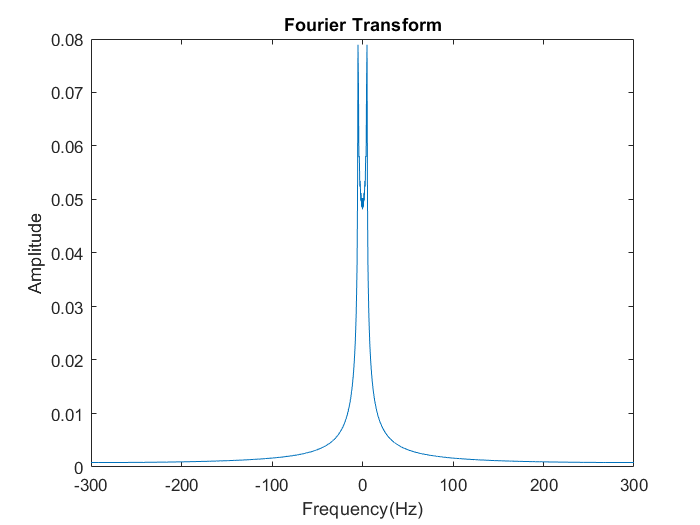


fourier = fftshift(fft(x)) / fs;
f = linspace(-0.5, 0.5, length(x)) * fs;

figure
plot(f, abs(fourier));
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Fourier Transform");

## Part 2

### a.

In this section, the value for both Ac and mu is considered as unity. Using a for loop signals using different carrier frequencies are generated. Since the sampling frequency is 600Hz, the highest frequency available in the signals must not reach fs/2 = 300Hz, so if we set fc equal to 600Hz or 1200Hz, beacause of aliasing, the modulation cannot be observed via digital sampling, and for the carrier frequency is a multiple of sampling frequency cos(wct) equals 1 at each smapling point and the output and input are the same. The maximum carrier frequency that can be used with this sampling rate is fs/2 - W where W is the bandwidth of the message. Assuming that W is much less than fc, the maximum carrier frequency is a little bit lower than 300Hz.

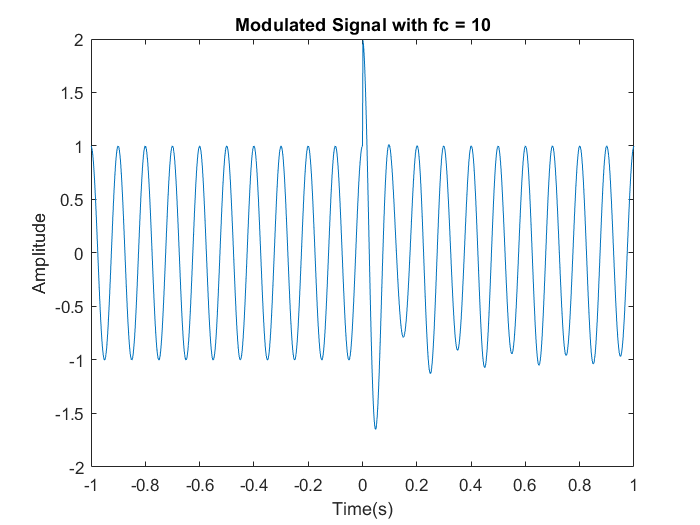

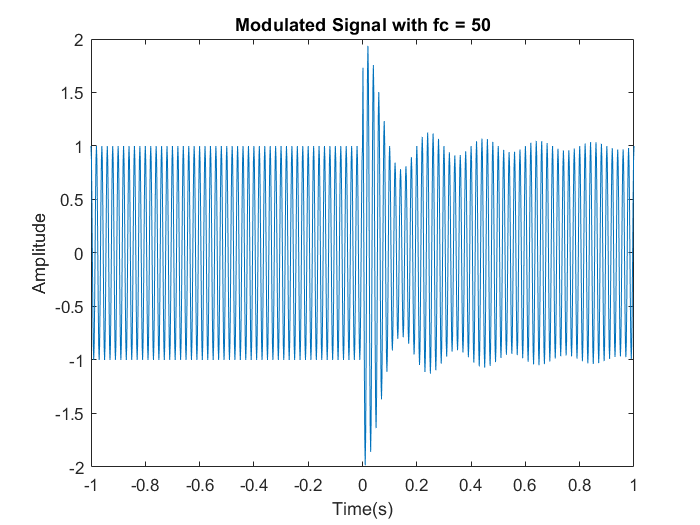

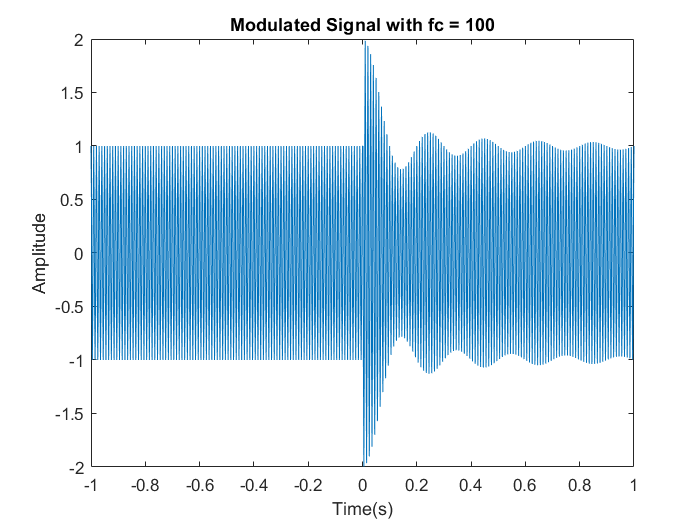

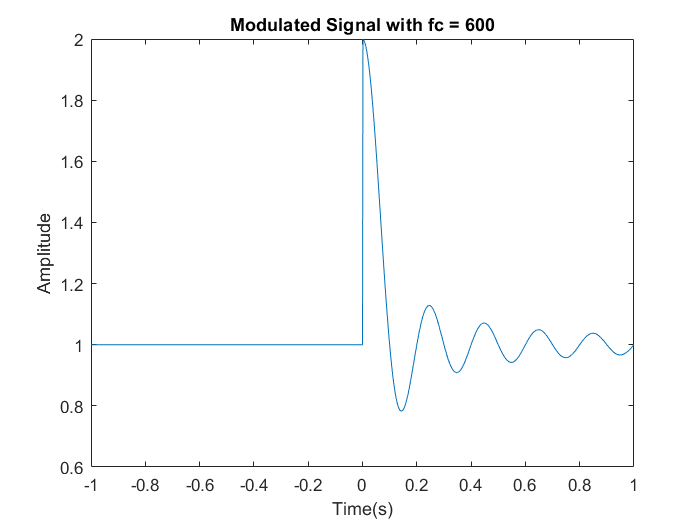

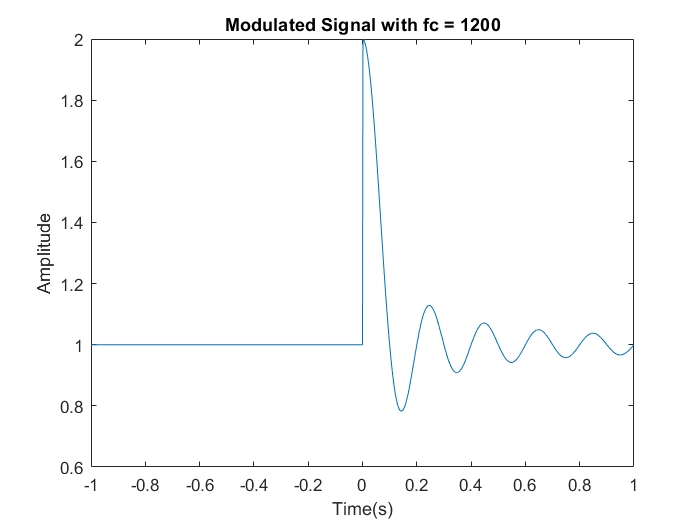

Ac = 1;
mu = 1;
for fc = [10 50 100 600 1200]
    x_c = conventional_am(x, Ac, mu, fc);
    figure
    plot(t, x_c);
    xlabel("Time(s)");
    ylabel("Amplitude");
    title("Modulated Signal with fc = " + fc);
end

## b.

The carrier frequency is set to 100Hz and the frequency domain representaion of the modulated signal is shown in the following image.The plot shows peaks at 200Hz frequency which is a result of the carrier signal. Also the shifted and scaled  version of the original message signal can be observed at 200Hz frequency.

fc = 100

fc = 100

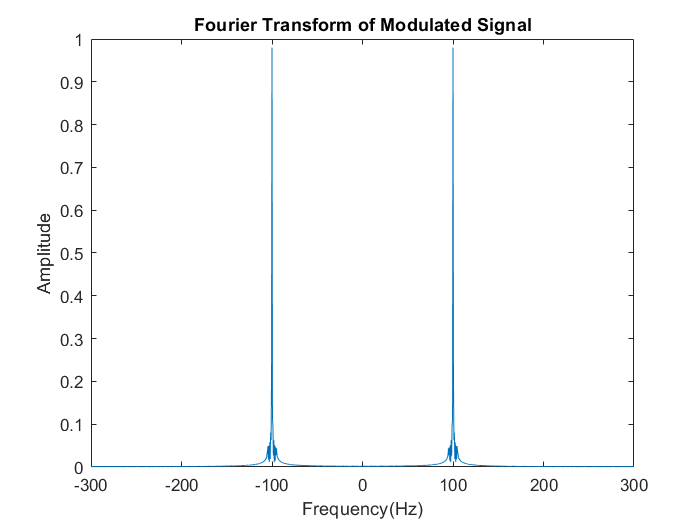

x_c = conventional_am(x, Ac, mu, fc);
fourier_m = fftshift(fft(x_c)) / fs;

figure
plot(f, abs(fourier_m));
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Fourier Transform of Modulated Signal");

## c.

The function for demodulating the conventional AM is implemented in conventional_am_demod.m file and is used in the next sections.

## d.

The time and frequency domain representation of y(t) and z(t) are plotted below. Y(f) consists of the sum of scaled, shifted by 200Hz, and not shifted versions of message signal and cosine carrier signals at 200Hz and a DC value.

Z(f) only consists of the sum of the DC value and a scaled version of the message signal.

The demodulated signal and the original message signal are also shown in the same figure and can be easily compared. They are the same at almost every points except the sharp angles which consist of high frequencies and are filtered via the lowpass filter.

Also the mean square error of the demodulated signal is calculated and equals 5.4e-4.

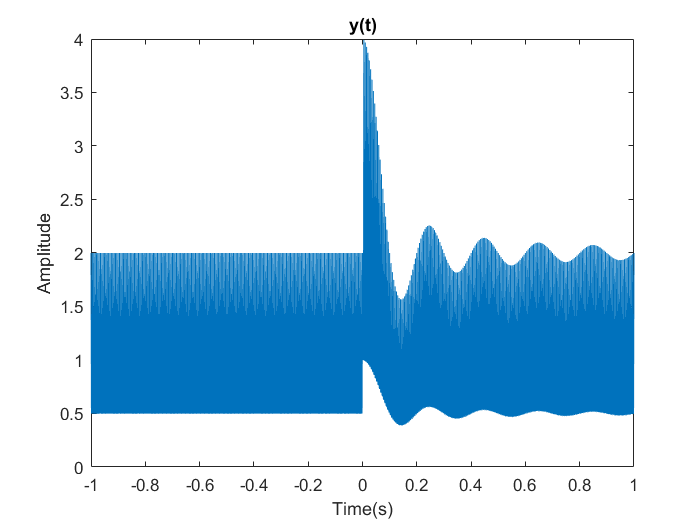

[x_m, y, z] = conventional_am_demod(x_c, Ac, mu, fc);

figure
plot(t, y);
xlabel("Time(s)");
ylabel("Amplitude")
title("y(t)");

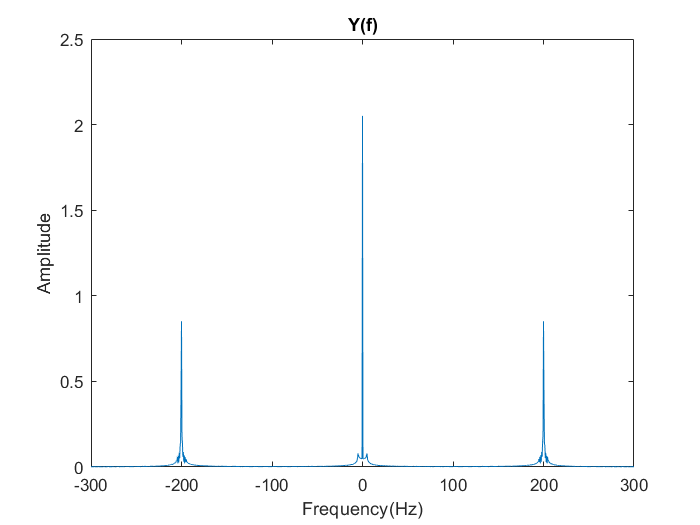


figure
plot(f, abs(fftshift(fft(y))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Y(f)")

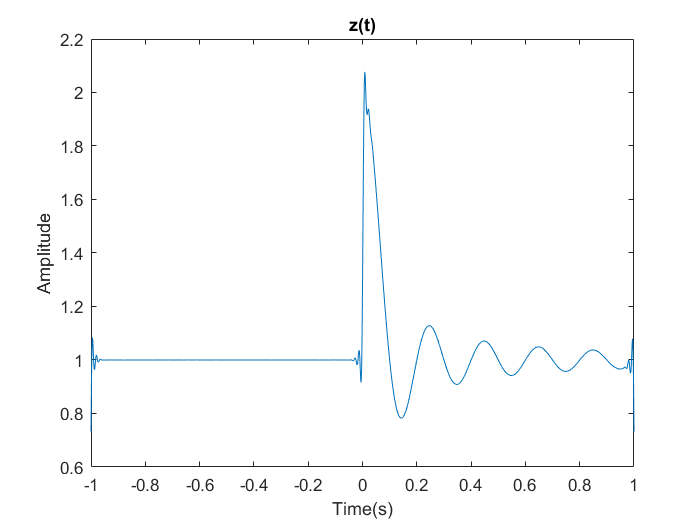


figure
plot(t, z);
xlabel("Time(s)");
ylabel("Amplitude");
title("z(t)");

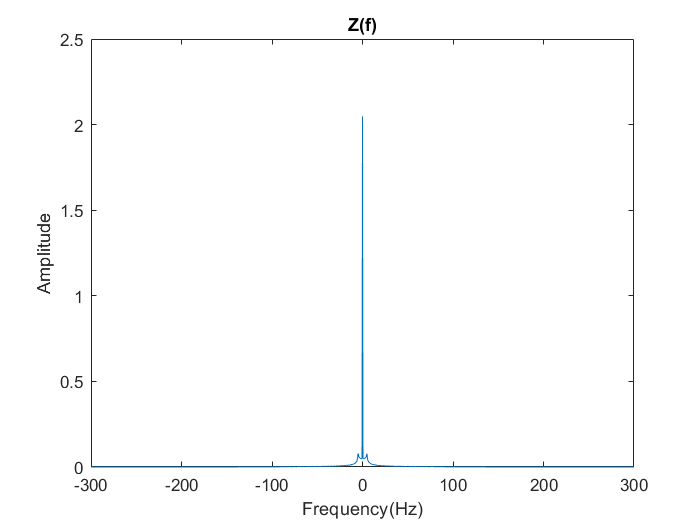


figure
plot(f, abs(fftshift(fft(z))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Z(f)")

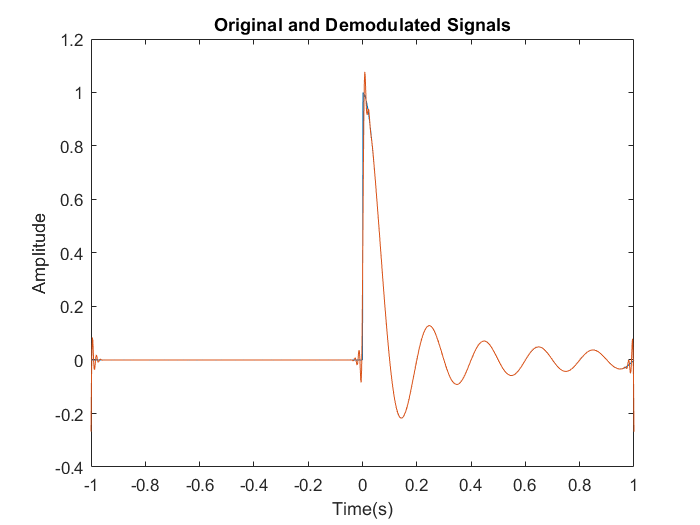


figure
plot(t, x);
hold on
plot(t, x_m);
xlabel("Time(s)");
ylabel("Amplitude");
title("Original and Demodulated Signals");


MSE = mean((x - x_m) .^ 2)

MSE = 5.4097e-04

## e.

By varying $\mu \;$we can obtain the plot of the MSE of the signal with respect to $\mu \;$. As $\mu \;$approaches zero, the error increases for the numeric quantization error and the data loss due to filtering get more noticable compared to the sent message signal energy. Because of use of envelope detector, $\mu \;$also must always be considered between -1 and 1, so the values of $\mu \;$where their magnitude is greater than 1 is not worthy of analyzing. The ideal value of $\mu \;$is 1, and considering a margin for undesired variations in data, which may result to values of greater than 1 in message, the ideal value of $\mu \;$will be about 0.95. Also it is worthy of note that if we set low values to $\mu \;$, the effect of noise will be enormous on the output data.

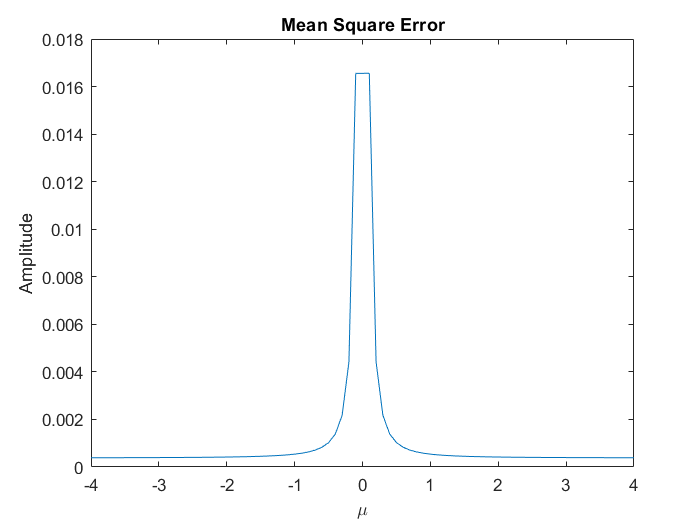

mu = [[-4 : 0.1 : -0.1], [0.1 : 0.1 : 4]];
MSE = zeros(size(mu));
for i = 1 : length(mu)
    x_c = conventional_am(x, Ac, mu(i), fc);
    [x_m, ~, ~] = conventional_am_demod(x_c, Ac, mu(i), fc);
    MSE(i) = mean((x - x_m) .^ 2);
end

figure
plot(mu, MSE)
xlabel("\mu");
ylabel("Amplitude");
title("Mean Square Error");

## f.

By varying fc and calculating the MSE of the demodulated signal, we can obtain the following image.

When fc is close to zero, i.e. is lower than the message signal bandwidth, the error is high for the modulated signal has aliasing effects with it. Since the two shifted versions of the signal overlap and the modulated signal cannot be recovered.

In a range between the message bandwidth and fs / 2 = 300Hz minus the signal bandwidth, the error is so low and negligible. For the frequency components of the message are apart from each other in the modulated signal and can be recovered usign demodulators.

At frequencies close to fs / 2 = 300Hz the error starts increasing since the sampling rate is lower than the Nyquist rate and causes data loss and aliasing in the frequency domain.

If the modulation frequency exceeds fs / 2 = 300Hz by a large amount, the behavior of the error is periodic because in digital systems, if the frequency of a sine wave gets higher than nyquist rate, it looks like the frequency is starting again from zero.

The optimized carrier frequency can be 150Hz because the MSE is minimized at that frequency.

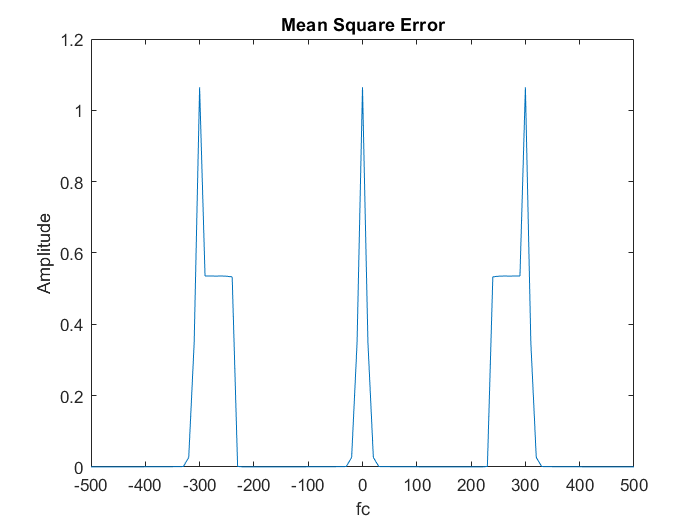


mu = 1;
fc = -500 : 10 : 500;
MSE = zeros(size(fc));
for i = 1 : length(fc)
    x_c = conventional_am(x, Ac, mu, fc(i));
    [x_m, ~, ~] = conventional_am_demod(x_c, Ac, mu, fc(i));
    MSE(i) = mean((x - x_m) .^ 2);
end

figure
plot(fc, MSE)
xlabel("fc");
ylabel("Amplitude");
title("Mean Square Error");

## Part 3

### a.

Assuming Ac = 1, the signal modulates the carrier signals with different frequencies, and the result is shown beneathe. 

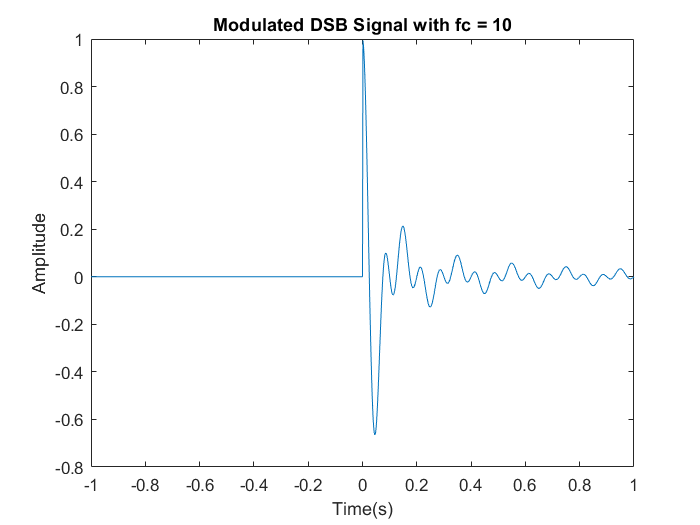

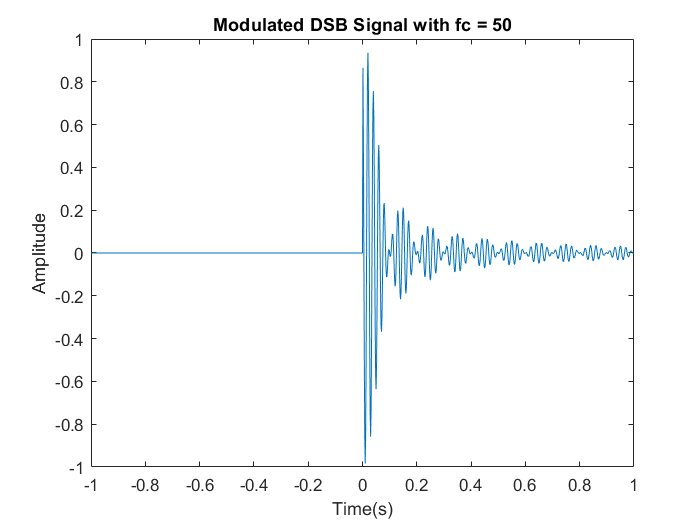

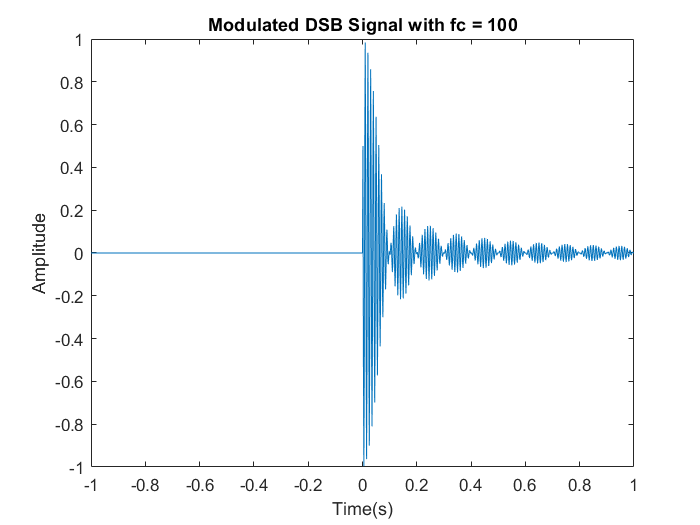

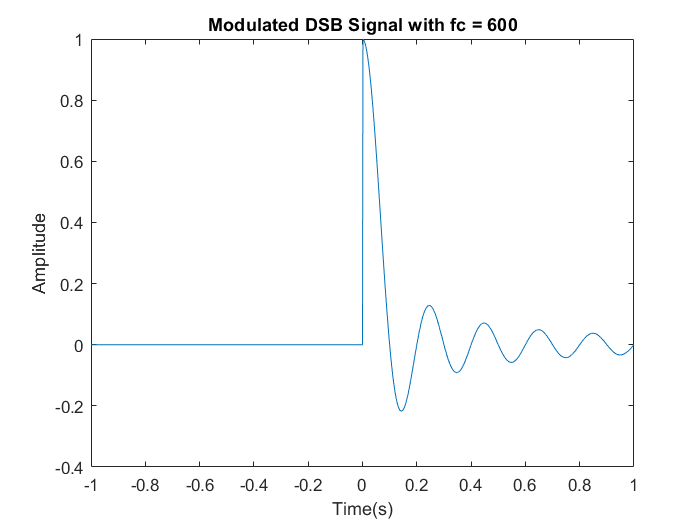

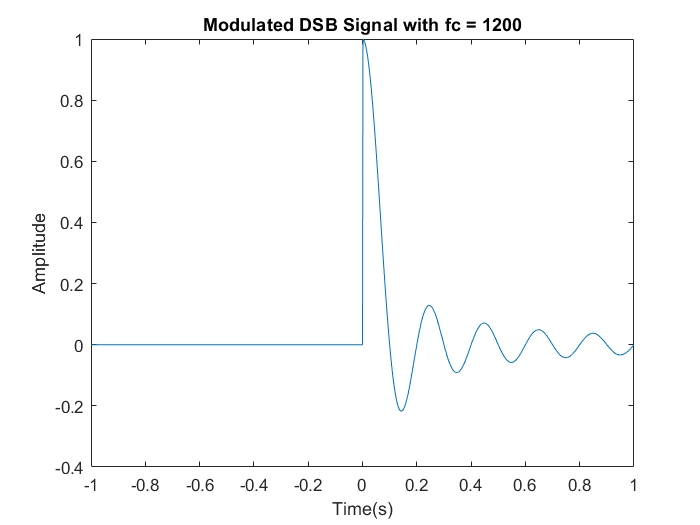

Ac = 1;
for fc = [10 50 100 600 1200]
    x_c = dsb_am(x, Ac, fc);
    figure
    plot(t, x_c);
    xlabel("Time(s)");
    ylabel("Amplitude");
    title("Modulated DSB Signal with fc = " + fc);
end

### b.

In this section we set fc = 100Hz. Then amplitude of the fourier transform of the modulated signal is plotted. As it can be seen, the image is the sum of two scaled by half of Ac and shifted by fc versions of the original message's spectrum.

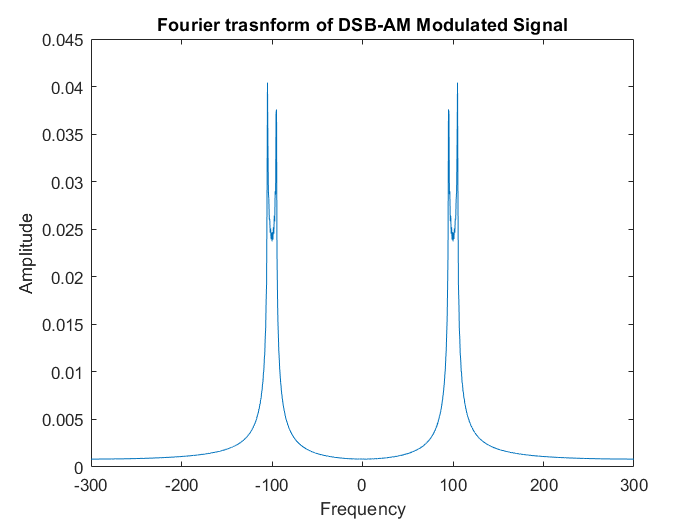

fc = 100;
x_c = dsb_am(x, Ac, fc);

fourier_c = fftshift(fft(x_c)) / fs;

figure
plot(f, abs(fourier_c));
xlabel("Frequency");
ylabel("Amplitude");
title("Fourier trasnform of DSB-AM Modulated Signal");

### c.

In the following section, the DSB-AM modulated signal is generated using Conventional AM Modulator, and the result is compared with the result of the previouse part. The MSE of this method equals 1.5e-33 which is negligible.

x_c_CAM = conventional_am(x / 2, Ac, 1, fc) - conventional_am(-x / 2, Ac, 1, fc);
MSE = mean((x_c_CAM - x_c) .^ 2)

MSE = 1.5238e-33

### d.

In this section, for lowpass filter, it is assumed that hte signal bandwidth does not exceed 100Hz. The function is used in the following sections and its implementation code is in dsb_am_demod.m file.

### e.

The demodulator implemented in section d is used for obtaining the message signal. The signals y(t) and z(t) are also shown in the following figures. Y(f) is the sum of shifted by 200Hz, not shifted, scaled by Ac and 2Ac of the origianl message. After using the lowpass filter, in z(t), only the scaled version of the original message is left. Finally the origianl and demodulated message signals are shown in the same image and can be compared easily. It is clear that they match at many poins whilte at sharp angles they may be different from each other, for they are consisted of high frequencies while we have filtered them.

Also the mean square error of the demodulated signal equals 3.8e-4 which is negligible.

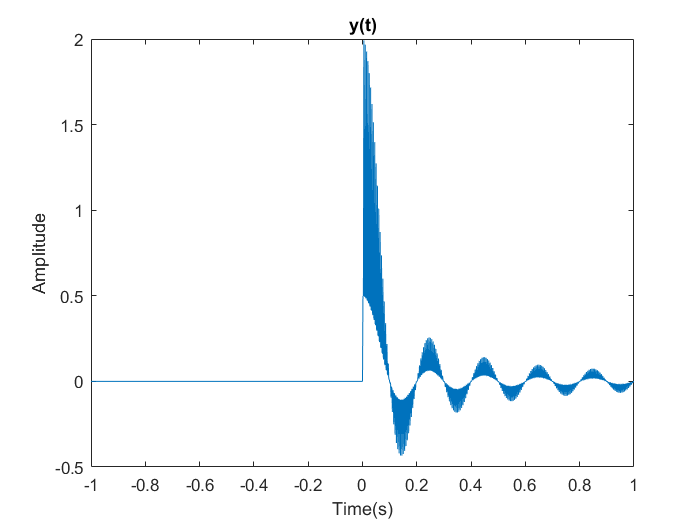

[x_m, y, z] = dsb_am_demod(x_c, Ac, fc);

figure
plot(t, y);
xlabel("Time(s)");
ylabel("Amplitude")
title("y(t)");

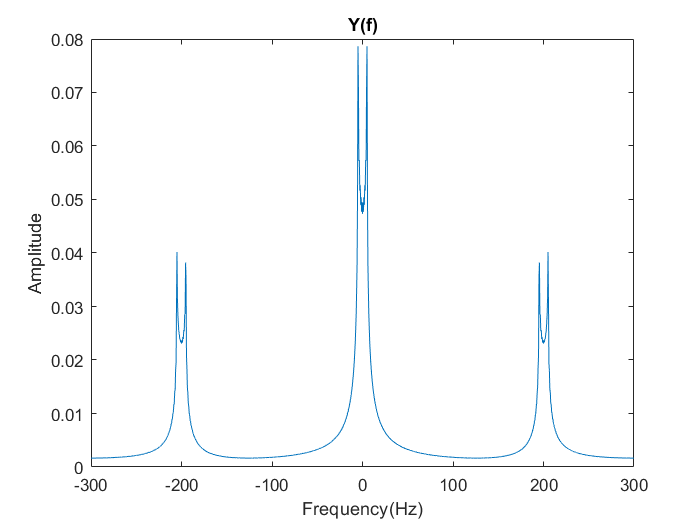


figure
plot(f, abs(fftshift(fft(y))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Y(f)")

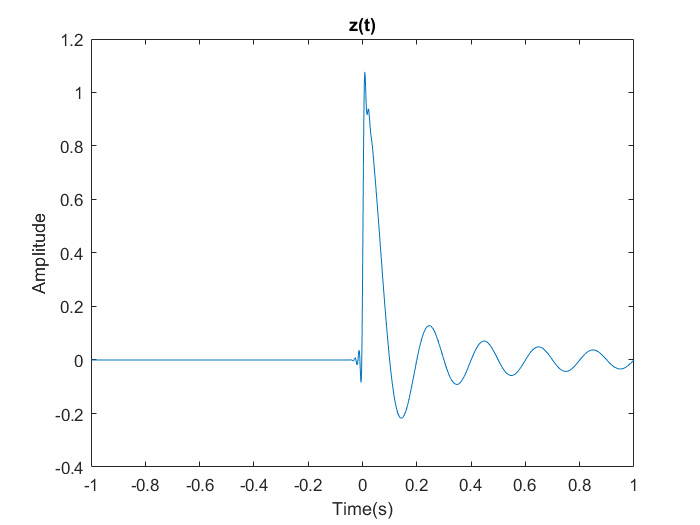


figure
plot(t, z);
xlabel("Time(s)");
ylabel("Amplitude");
title("z(t)");

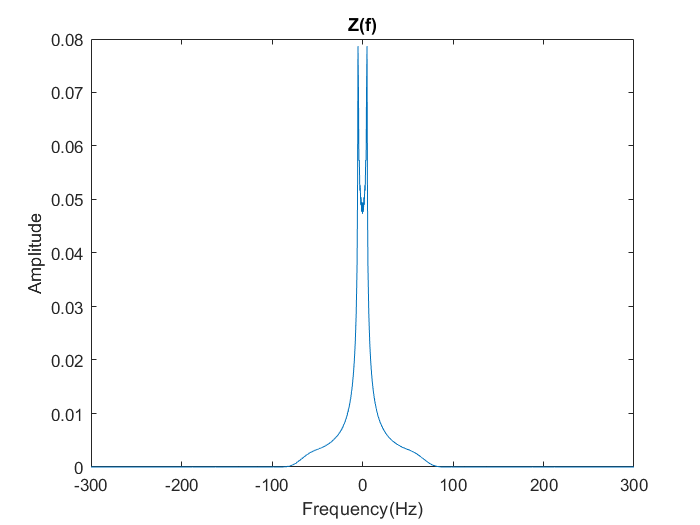


figure
plot(f, abs(fftshift(fft(z))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Z(f)")

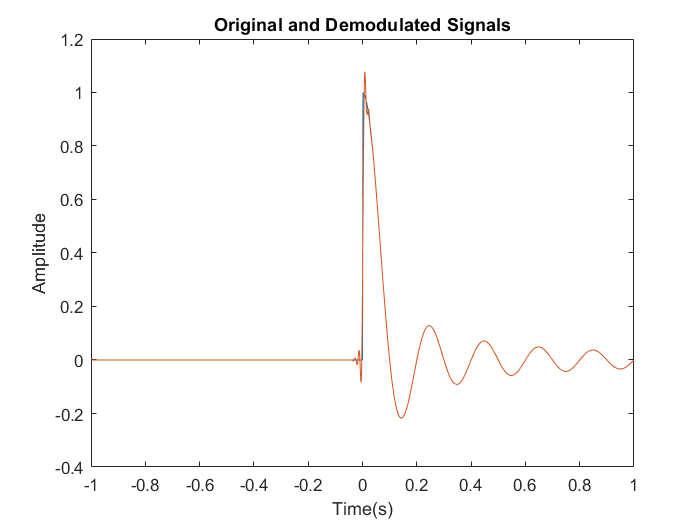


figure
plot(t, x);
hold on
plot(t, x_m);
xlabel("Time(s)");
ylabel("Amplitude");
title("Original and Demodulated Signals");


MSE = mean((x - x_m) .^ 2)

MSE = 3.7880e-04

## f.

The mean square error of the demodulated signal with respect to the carrier frequency is plotted in the following image.

The justification of this part is much like section f in part 2.

When fc is close to zero, i.e. is lower than the message signal bandwidth, the error is high for the modulated signal has aliasing effects with it. Since the two shifted versions of the signal overlap and the modulated signal cannot be recovered.

In a range between the message bandwidth and fs / 2 = 300Hz minus the signal bandwidth, the error is so low and negligible. For the frequency components of the message are apart from each other in the modulated signal and can be recovered usign demodulators.

At frequencies close to fs / 2 = 300Hz the error starts increasing since the sampling rate is lower than the Nyquist rate and causes data loss in the frequency domain.

If the modulation frequency exceeds fs / 2 = 300Hz by a large amount, the behavior of the error is periodic because in digital systems, if the frequency of a sine wave gets higher than nyquist rate, it looks like the frequency is starting again from zero.

The ideal modulation frequency can be 150Hz since it has the minimum MSE without overlapping.

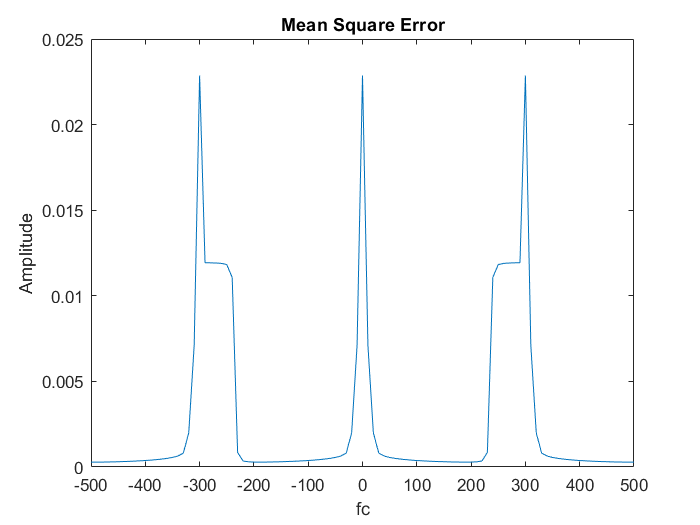

fc = -500 : 10 : 500;
MSE = zeros(size(fc));
for i = 1 : length(fc)
    x_c = dsb_am(x, Ac, fc(i));
    [x_m, ~, ~] = dsb_am_demod(x_c, Ac, fc(i));
    MSE(i) = mean((x - x_m) .^ 2);
end

figure
plot(fc, MSE)
xlabel("fc");
ylabel("Amplitude");
title("Mean Square Error");

## Part 4

The advantage of SSB modulation over DSB modulation is in the optimized use of bandwidth. Assuming the message signal has a bandwidth of W, the SSB modulated signal will also have a bandwidth of W while the DSB modulated signal has 2W bandwidth.

The functions for SSB modulating signals are implemented in ussb_am.m and lssb_am.m files.

### a.

The plot of USSB and LSSB AM modulated signals can be observed below. Also their fourier transform magnitude are plotted. Here, it is assumed that Ac equals one.

As it can be observed, the LSSB modulated signal consists of the left side of the spectrum of the message signal and the USSB modulated signal is consisted of the right side of the spectrum of the original message signal.

fc = 100;
Ac = 1

Ac = 1

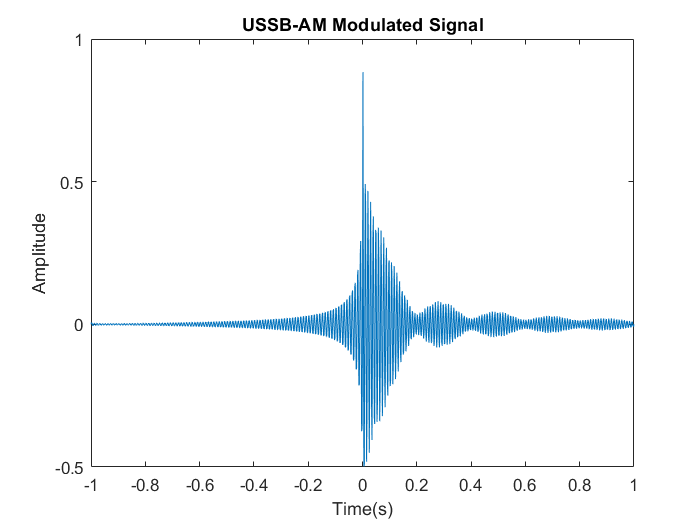

x_c_u = ussb_am(x, Ac, fc);

figure;
plot(t, x_c_u);
xlabel("Time(s)");
ylabel("Amplitude")
title("USSB-AM Modulated Signal");

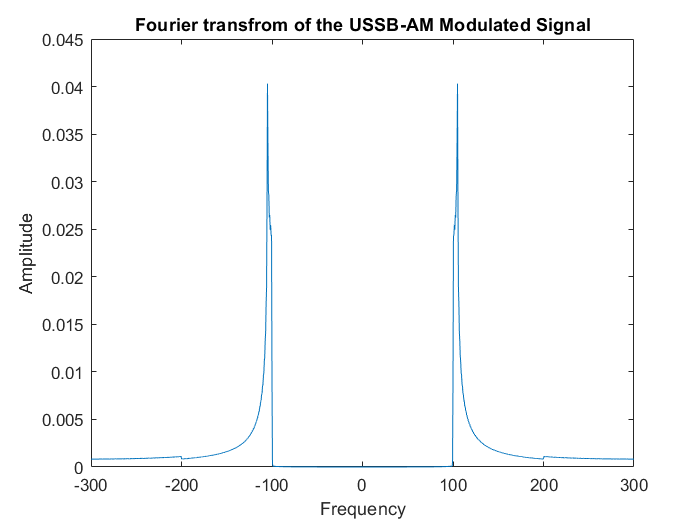


fourier_u = fftshift(fft(x_c_u)) / fs;

figure
plot(f, abs(fourier_u));
xlabel("Frequency");
ylabel("Amplitude");
title("Fourier transfrom of the USSB-AM Modulated Signal")

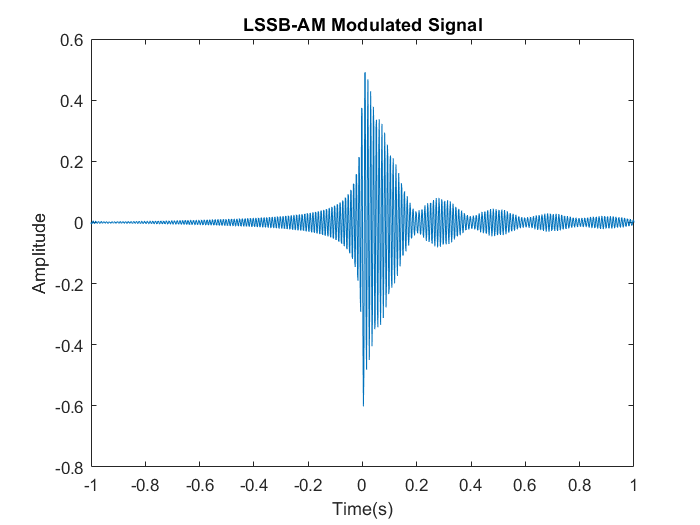


x_c_l = lssb_am(x, Ac, fc);

figure;
plot(t, x_c_l);
xlabel("Time(s)");
ylabel("Amplitude")
title("LSSB-AM Modulated Signal");

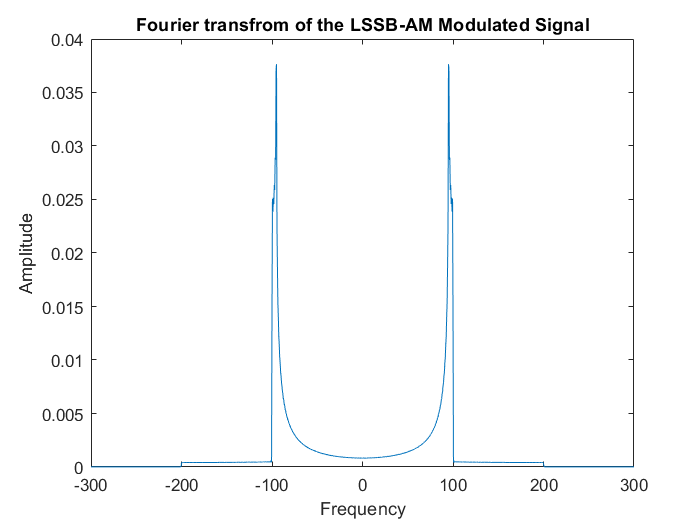


fourier_l = fftshift(fft(x_c_l)) / fs;

figure
plot(f, abs(fourier_l));
xlabel("Frequency");
ylabel("Amplitude");
title("Fourier transfrom of the LSSB-AM Modulated Signal");

### b.

The demodulator is implemented in ssb_am_demod.m file. In the demodulator it is assumed that the sampling frequency equals 600Hz. The signals y(t) and z(t) are also shown in the following images.

Y(f) consists of the sum of scaled original signal and two half bands of the signal placed at 200Hz.

Z(f) equals the scaled version of the original signal.

The demodulated signal and the original message signal are also both shown in the same plot. Also the MSE of the demodulated signals are calculated and equal 5.3e-4 and 3.3e-4 for LSSB and USSB respectively which are negligible values.

Below are the plots for the USSB-AM modulated signal:

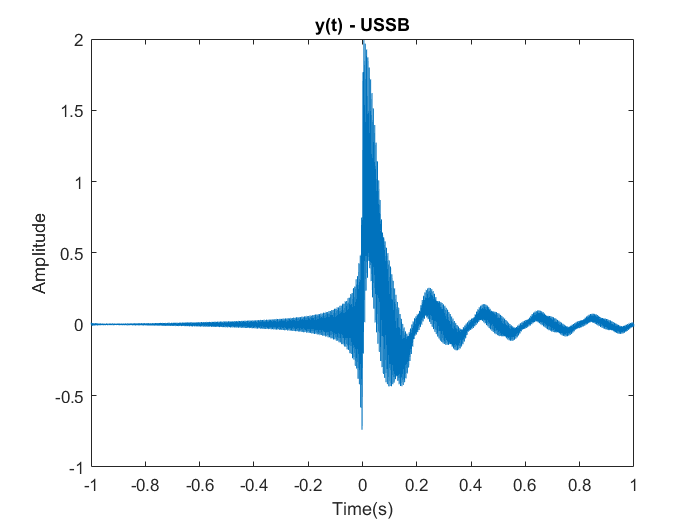

[x_m, y, z] = ssb_am_demod(x_c_u, Ac, fc);

figure
plot(t, y);
xlabel("Time(s)");
ylabel("Amplitude")
title("y(t) - USSB");

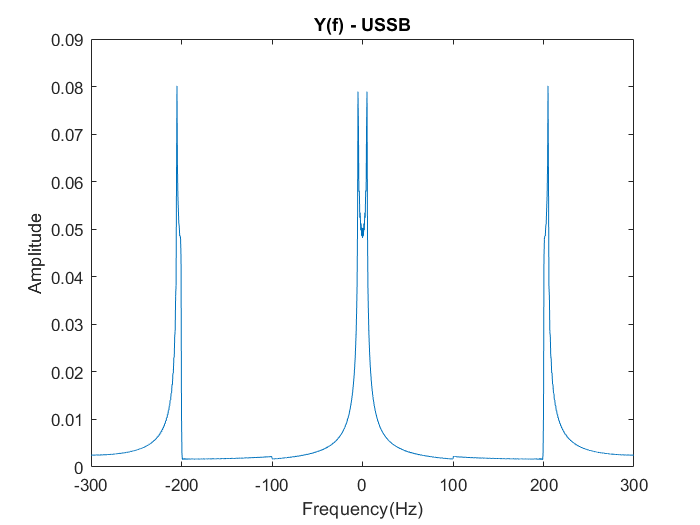


figure
plot(f, abs(fftshift(fft(y))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Y(f) - USSB")

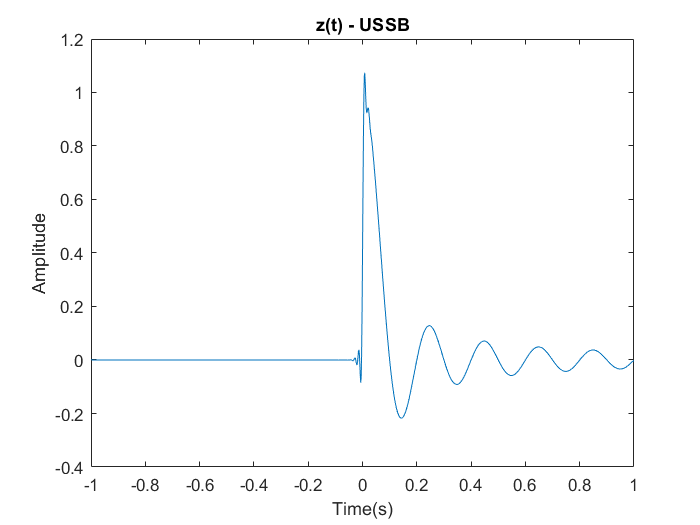


figure
plot(t, z);
xlabel("Time(s)");
ylabel("Amplitude");
title("z(t) - USSB");

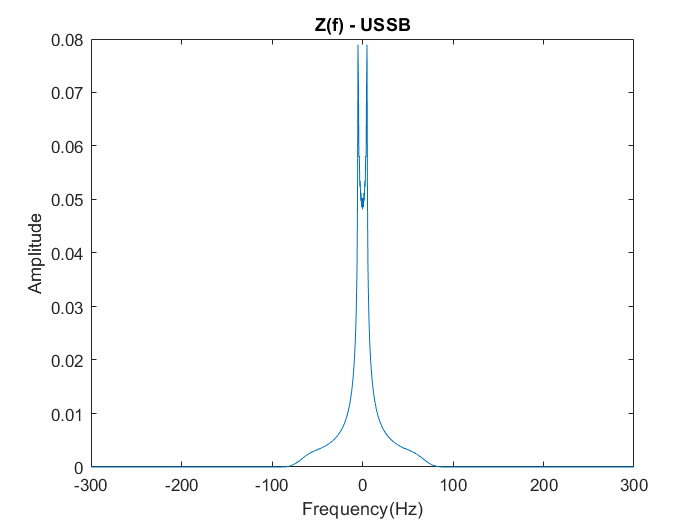


figure
plot(f, abs(fftshift(fft(z))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Z(f) - USSB")

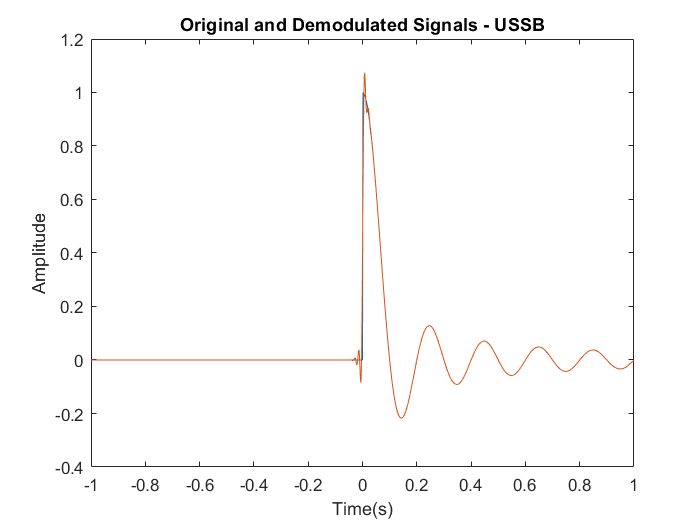


figure
plot(t, x);
hold on
plot(t, x_m);
xlabel("Time(s)");
ylabel("Amplitude");
title("Original and Demodulated Signals - USSB");


MSE = mean((x - x_m) .^ 2)

MSE = 3.2747e-04

And below are the plots for the LSSB-AM modulated signal:

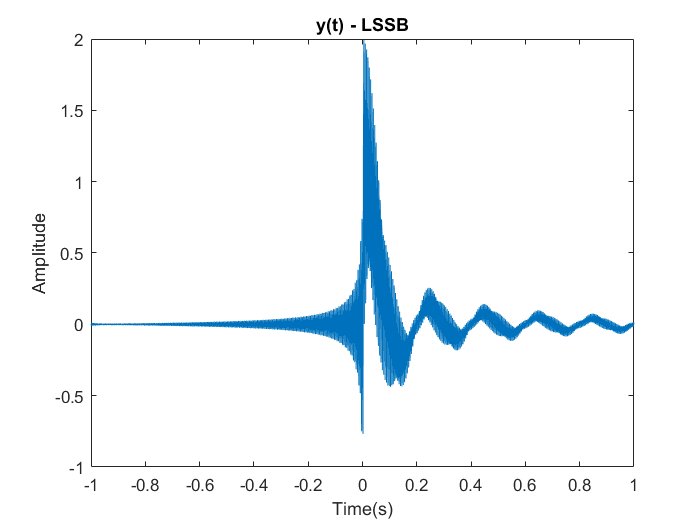

[x_m, y, z] = ssb_am_demod(x_c_l, Ac, fc);

figure
plot(t, y);
xlabel("Time(s)");
ylabel("Amplitude")
title("y(t) - LSSB");

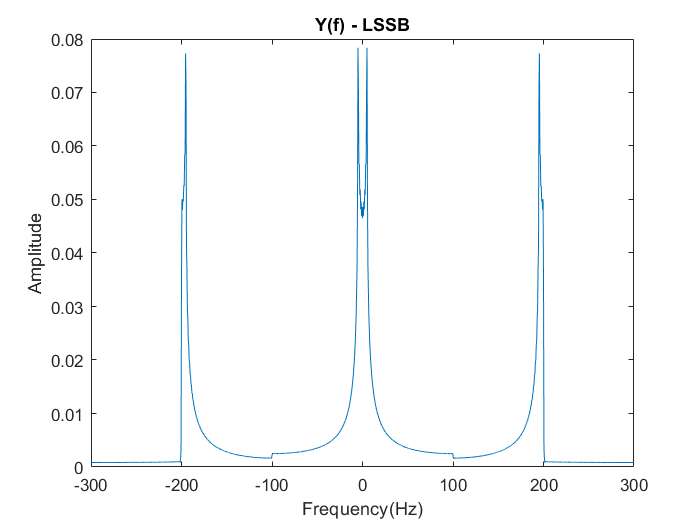


figure
plot(f, abs(fftshift(fft(y))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Y(f) - LSSB")

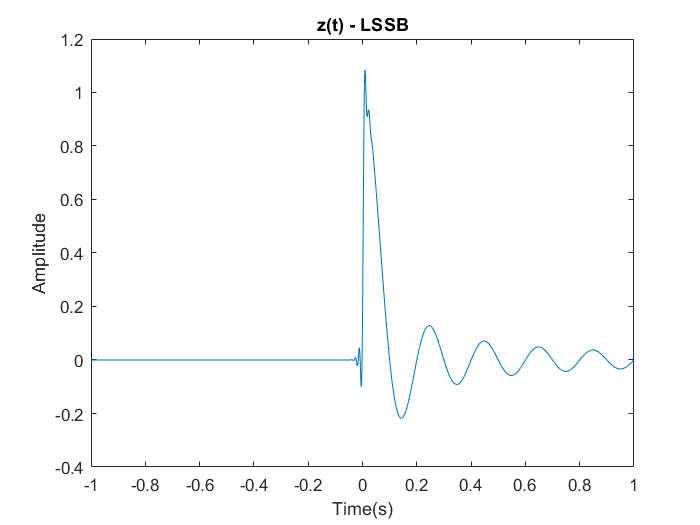


figure
plot(t, z);
xlabel("Time(s)");
ylabel("Amplitude");
title("z(t) - LSSB");

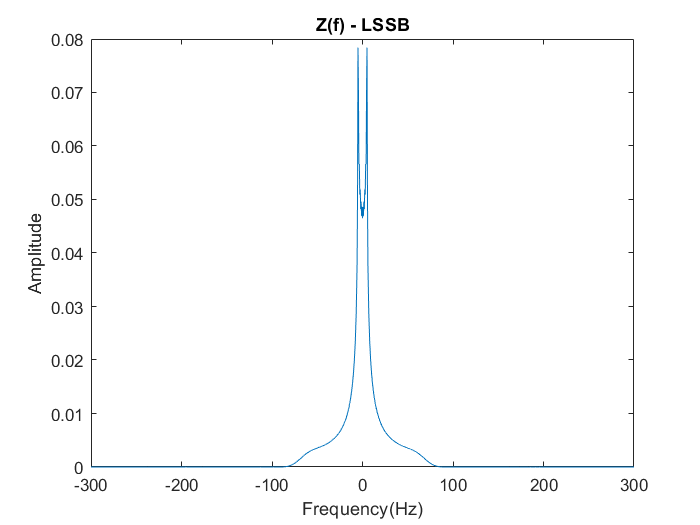


figure
plot(f, abs(fftshift(fft(z))) / fs);
xlabel("Frequency(Hz)");
ylabel("Amplitude");
title("Z(f) - LSSB")

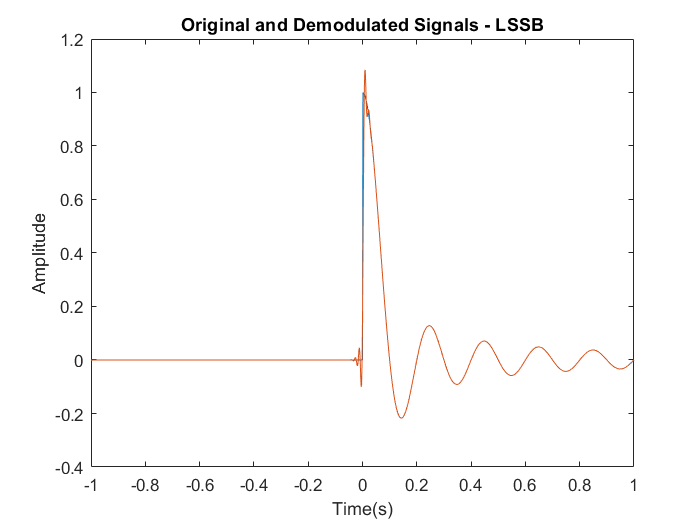


figure
plot(t, x);
hold on
plot(t, x_m);
xlabel("Time(s)");
ylabel("Amplitude");
title("Original and Demodulated Signals - LSSB");


MSE = mean((x - x_m) .^ 2)

MSE = 5.2786e-04

## Part 5

## a.

Below are the plots of the demodulated signals. It is clear that signals are not recoverable and suffer from aliasing and also are consisted of the product of the message signal and an oscillating term.

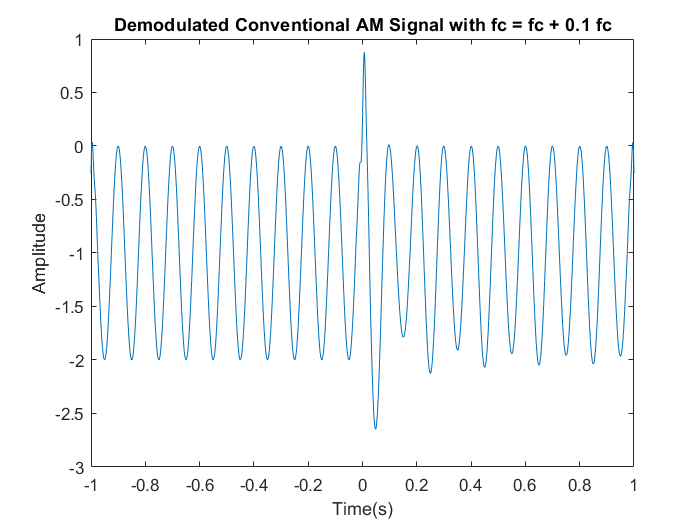

x_c = zeros(4, length(x));
Ac = 1;
mu = 1;
fc = 100;
x_c_c = conventional_am(x, Ac, mu, fc);
x_c_d = dsb_am(x, Ac, fc);
x_c_u = ussb_am(x, Ac, fc);
x_c_l = lssb_am(x, Ac, fc);

f_prime_plus = 1.1 * fc;
f_prime_minus = 0.9 * fc;

x_m_c_plus = conventional_am_demod(x_c_c, Ac, mu, f_prime_plus);
x_m_d_plus = dsb_am_demod(x_c_d, Ac, f_prime_plus);
x_m_u_plus = ssb_am_demod(x_c_u, Ac, f_prime_plus);
x_m_l_plus = ssb_am_demod(x_c_l, Ac, f_prime_plus);

x_m_c_minus = conventional_am_demod(x_c_c, Ac, mu, f_prime_minus);
x_m_d_minus = dsb_am_demod(x_c_d, Ac, f_prime_minus);
x_m_u_minus = ssb_am_demod(x_c_u, Ac, f_prime_minus);
x_m_l_minus = ssb_am_demod(x_c_l, Ac, f_prime_minus);

figure
plot(t, x_m_c_plus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated Conventional AM Signal with fc = fc + 0.1 fc");

"MSE Error of conventional AM demodulated signal with fc = fc + 0.1 fc :" + mean((x_m_c_plus - x) .^ 2)

ans = "MSE Error of conventional AM demodulated signal with fc = fc + 0.1 fc :1.608"

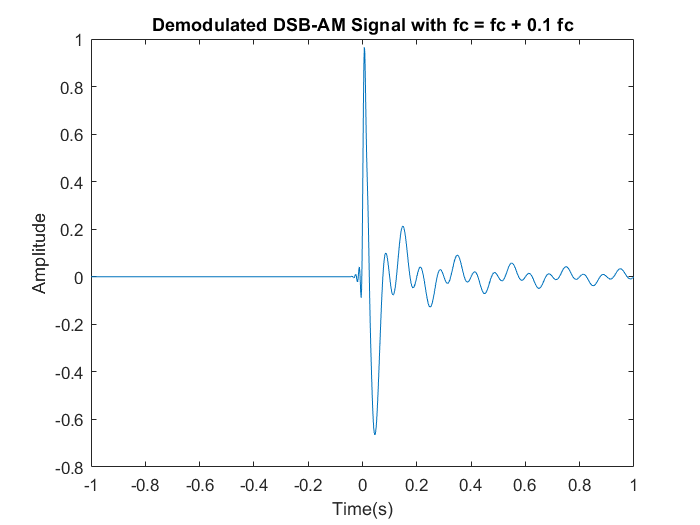


figure
plot(t, x_m_d_plus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated DSB-AM Signal with fc = fc + 0.1 fc");

"MSE Error of DSB-AM demodulated signal with fc = fc + 0.1 fc :" + mean((x_m_d_plus - x) .^ 2)

ans = "MSE Error of DSB-AM demodulated signal with fc = fc + 0.1 fc :0.037186"

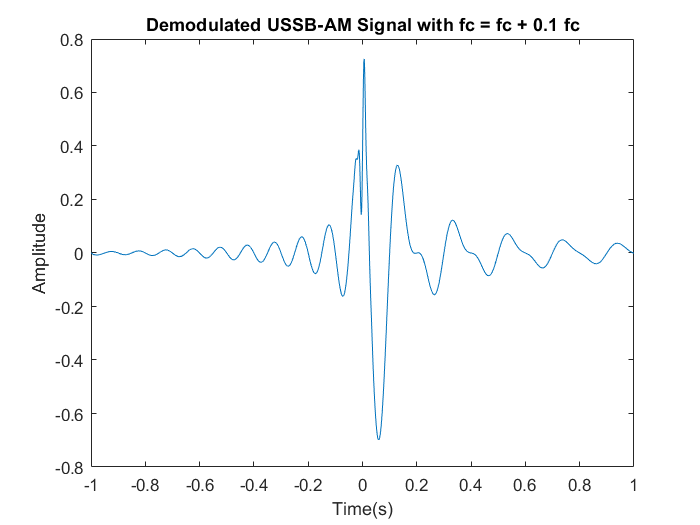


figure
plot(t, x_m_u_plus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated USSB-AM Signal with fc = fc + 0.1 fc");

"MSE Error of USSB-AM demodulated signal with fc = fc + 0.1 fc :" + mean((x_m_u_plus - x) .^ 2)

ans = "MSE Error of USSB-AM demodulated signal with fc = fc + 0.1 fc :0.052091"

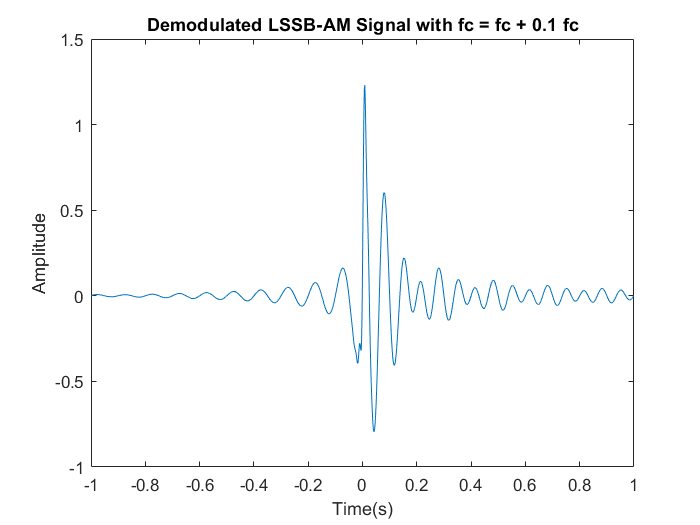


figure
plot(t, x_m_l_plus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated LSSB-AM Signal with fc = fc + 0.1 fc");

"MSE Error of LSSB-AM demodulated signal with fc = fc + 0.1 fc :" + mean((x_m_l_plus - x) .^ 2)

ans = "MSE Error of LSSB-AM demodulated signal with fc = fc + 0.1 fc :0.039807"

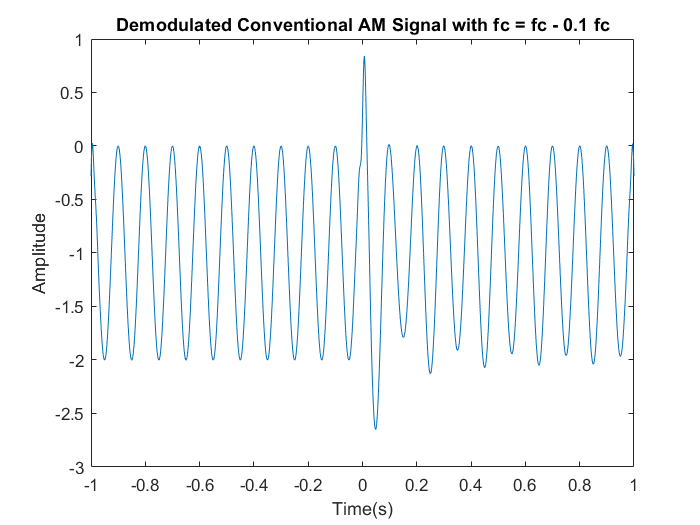


figure
plot(t, x_m_c_minus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated Conventional AM Signal with fc = fc - 0.1 fc");

"MSE Error of conventional AM demodulated signal with fc = fc - 0.1 fc :" + mean((x_m_c_minus - x) .^ 2)

ans = "MSE Error of conventional AM demodulated signal with fc = fc - 0.1 fc :1.61"

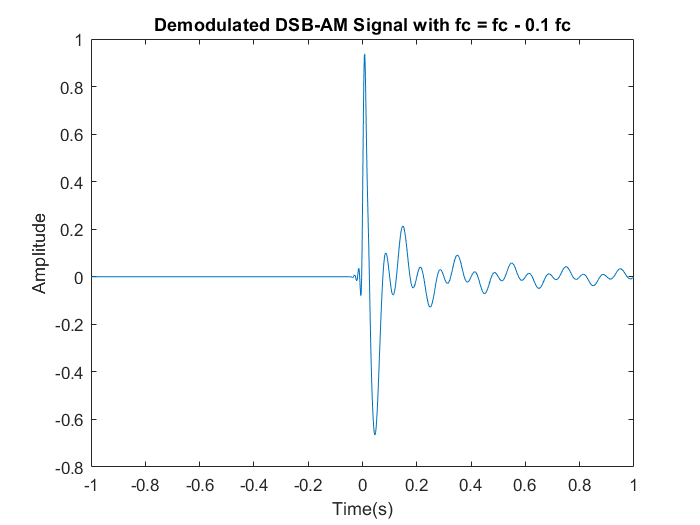


figure
plot(t, x_m_d_minus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated DSB-AM Signal with fc = fc - 0.1 fc");

"MSE Error of DSB-AM demodulated signal with fc = fc - 0.1 fc :" + mean((x_m_d_minus - x) .^ 2)

ans = "MSE Error of DSB-AM demodulated signal with fc = fc - 0.1 fc :0.037253"

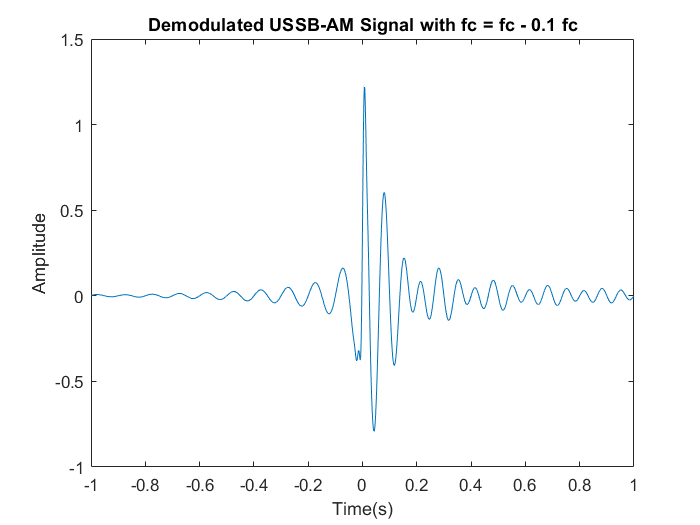


figure
plot(t, x_m_u_minus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated USSB-AM Signal with fc = fc - 0.1 fc");

"MSE Error of USSB-AM demodulated signal with fc = fc - 0.1 fc :" + mean((x_m_u_minus - x) .^ 2)

ans = "MSE Error of USSB-AM demodulated signal with fc = fc - 0.1 fc :0.039795"

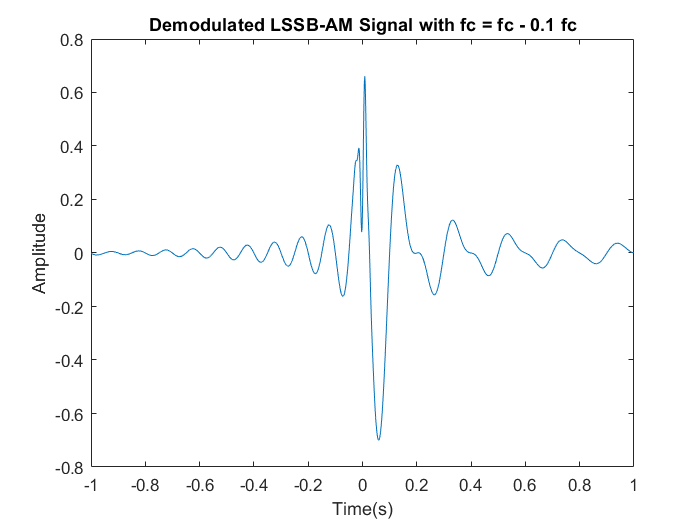


figure
plot(t, x_m_l_minus);
xlabel("Time(s)");
ylabel("Amplitude");
title("Demodulated LSSB-AM Signal with fc = fc - 0.1 fc");

"MSE Error of LSSB-AM demodulated signal with fc = fc - 0.1 fc :" + mean((x_m_l_minus - x) .^ 2)

ans = "MSE Error of LSSB-AM demodulated signal with fc = fc - 0.1 fc :0.052515"

## b.

The plot of the MSE of the signal with respect to $\Delta f$is shown in the following images for differend modulation methods.

It is clear that as $\Delta f$ gets closer to zero, the error decreases.

The conventional AM modulation is the most sensitive to $\Delta f$ and the SSB modulations are the least sensitive modulations to $\Delta f$.

The reason that the figures of conventional AM and DSB-AM are not symmetric is that the low-pass filter breaks the symmetry in adding $\Delta f$ and subtracting it from fc.

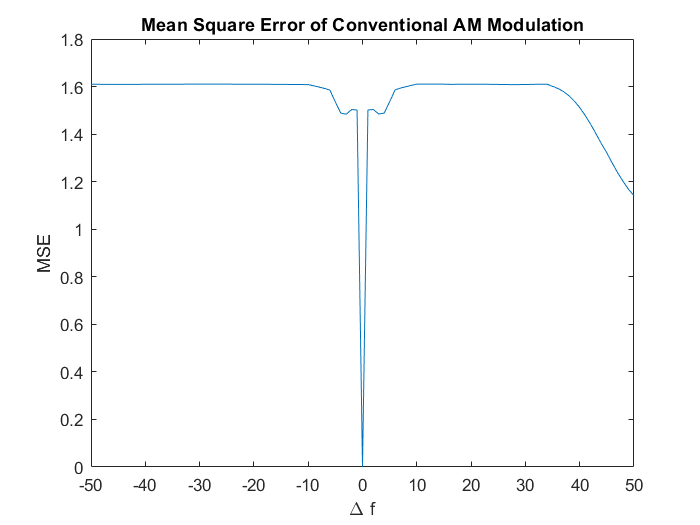

delta_f = -50 : 50;
f_prime = fc - delta_f;
MSE = zeros(4, length(f_prime));
for i = 1 : length(f_prime)
    MSE(1,i) = mean((x - conventional_am_demod(x_c_c, Ac, mu, f_prime(i))) .^ 2);
    MSE(2,i) = mean((x - dsb_am_demod(x_c_d, Ac, f_prime(i))) .^ 2);
    MSE(3,i) = mean((x - ssb_am_demod(x_c_u, Ac, f_prime(i))) .^ 2);
    MSE(4,i) = mean((x - ssb_am_demod(x_c_l, Ac, f_prime(i))) .^ 2);
end

figure
plot(delta_f, MSE(1, :));
xlabel("\Delta f");
ylabel("MSE")
title("Mean Square Error of Conventional AM Modulation")

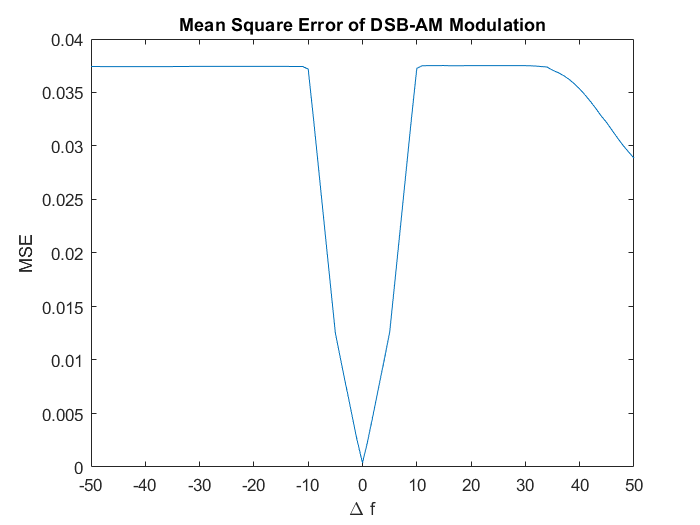


figure
plot(delta_f, MSE(2, :));
xlabel("\Delta f");
ylabel("MSE")
title("Mean Square Error of DSB-AM Modulation")

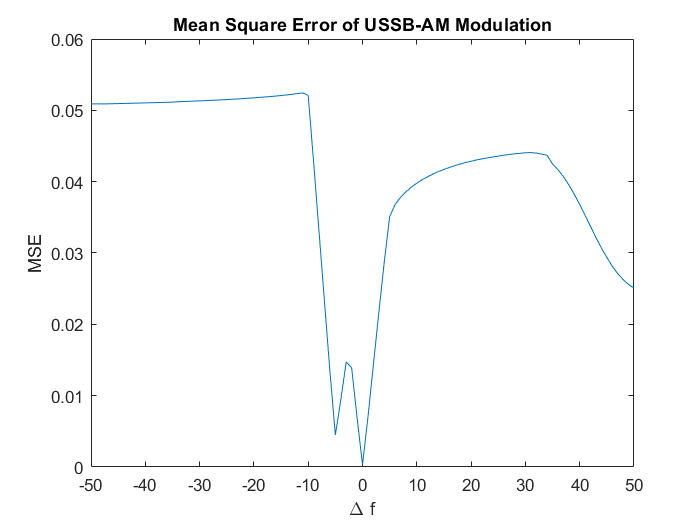


figure
plot(delta_f, MSE(3, :));
xlabel("\Delta f");
ylabel("MSE")
title("Mean Square Error of USSB-AM Modulation")

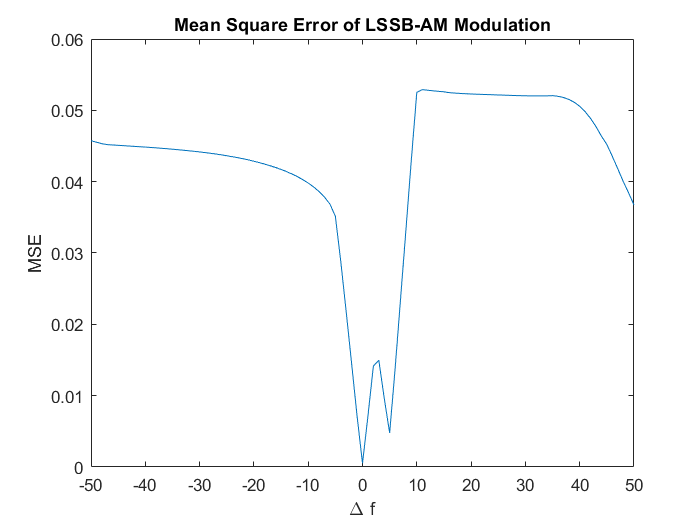


figure
plot(delta_f, MSE(4, :));
xlabel("\Delta f");
ylabel("MSE")
title("Mean Square Error of LSSB-AM Modulation")